# 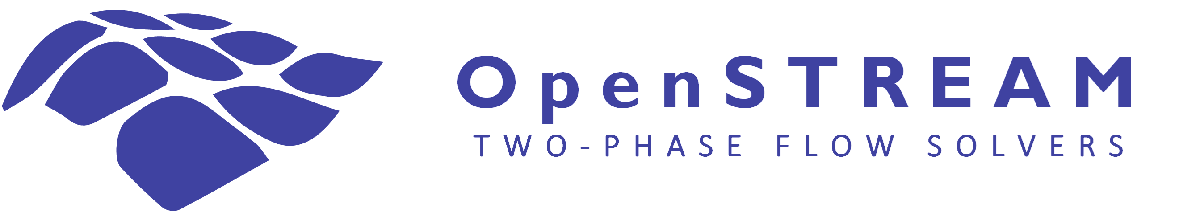

# Tutorial #7: Numerical convergence and solver diagnostics

This tutorial distinguishes pointwise convergence, pseudo-time convergence, and physical-time advancement, then shows how to inspect the stored initialization history.

Learning objectives:

- Interpret pointwise and temporal convergence information.

- Distinguish pseudo-time initialization from physical-time advancement.

- Inspect the variables controlling convergence.

- Understand how numerical settings influence convergence behavior.

- Apply convergence-improvement and solution-acceptance checks.

*Note: This tutorial is designed for use with output displayed inline (View > Output Inline) in the MATLAB Live Editor. Any animations are displayed in separate pop-up figure windows and can be played continuously or inspected one stored time step at a time. Animations and their controls are not preserved in static Markdown, HTML, or PDF exports.*

**Important**

*The physical models and closure relations selected in this tutorial are used for educational and demonstration purposes. Their use does not imply that they are appropriate, recommended, or validated for the simulated conditions. The calculated results should therefore be interpreted as illustrations of the solver framework and its capabilities, rather than as validated predictions. Before applying OpenSTREAM to a technical study, assess the assumptions, applicability range, and validation basis of every selected model.*

## Set up OpenSTREAM

Clear existing variables from the workspace.

clearvars

When this tutorial is run directly from the tutorials folder, the OpenSTREAM root directory is one level above the current folder.

osp = './..';
addpath(osp);

Import the Inputs packages.

import Inputs.*
import Solvers.*

## Baseline solver

Use the mixture solver as the baseline. As needed, repeat the workflow for the other solvers after the diagnostic pattern is understood.

% Construct the inputSet.
warning off
inputSet = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL1', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'DEFAULT', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial1.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');
warning on

% Create and solve the mixture solver.
import Solvers.Mixture.*
mixSolver = MixtureSolver(inputSet);
mixSolver.solve();

## Inspect the solver state

For each pseudo-time step, the solver reports the maximum point-iteration count, the axial node at which it occurs, and the maximum pointwise changes in the variables used to evaluate local convergence. These variables depend on the selected solver and its solved fields. In this example, the mixture solver reports changes in mixture mass flow rate, pressure, and mixture enthalpy. The decreasing iteration count indicates that the local nonlinear solution generally becomes easier to converge as the pseudo-time calculation approaches steady state.

The final STEADY-STATE CONVERGED line reports the maximum changes between the last two pseudo-time solutions. The steady-state solution is accepted when these temporal changes satisfy their convergence criteria and the pointwise iterations have also converged during the final pseudo-time step.

Record the final solver state and the number of stored pseudo-time iterations:

disp(mixSolver.STATE)
fprintf('Stored initialization states: %d\n',numel(mixSolver.mixtureInit));

## Plot pseudo-time convergence

Use the NULL solve mode to display the pseudo-time history used to obtain the initial steady-state solution. Adjust the display list to select the quantities of interest.

mixSolver.plotz([], ...
    'display', {'W','VR'}, ...
    'solveMode', 'NULL', ...
    'arrangement', 'horizontal', ...
    'resize', 1);

Each animation frame shows the axial solution at a stored pseudo-time step during steady-state initialization. The sequence begins from the initialization state assigned by the solver and progressively evolves toward the steady-state solution. The initialization state is a numerical starting point and should not necessarily be interpreted as a physically realizable flow condition.

Use the animation controls to play the complete pseudo-transient or move manually from one pseudo-time step to another. This view helps identify where the solution changes most strongly, which quantities evolve most slowly, and whether oscillations or other convergence difficulties occur. As the solution approaches steady state, the changes between successive animation frames should progressively decrease.

In this example, the mixture and phase mass flow rates, equilibrium quality, vapor mass quality, and void fraction evolve from their initialized distributions toward their final steady-state profiles. The animation provides a qualitative view of this evolution, while the solver’s pointwise and temporal convergence criteria determine whether steady-state convergence has been achieved.

## Outlet pseudo-time history

Plot the evolution at the outlet.

mixSolver.plott(mixSolver.NZ, ...
    'display', {'W','VR'}, ...
    'solveMode', 'NULL', ...
    'arrangement', 'horizontal', ...
    'resize', 1);

This figure displays the pseudo-time evolution of the selected quantities at the channel outlet. It complements the preceding axial animation by showing how the solution at one fixed location evolves from the initialization state assigned by the solver toward its final steady-state value.

The time histories can be used to identify quantities that converge slowly or exhibit oscillatory behavior. As steady state is approached, the changes between successive pseudo-time steps should progressively decrease. The plots provide a qualitative convergence diagnostic, while formal convergence is determined by the solver’s pointwise and temporal convergence criteria.

## Relaxation factors and pseudo-time step

Relaxation factors control how much of the newly calculated change is applied during each point iteration. A relaxation factor of one applies the complete calculated update, while a value smaller than one applies only a fraction of the update. Under-relaxation can improve numerical stability when the coupled nonlinear equations produce oscillatory or divergent iterations, but it generally increases the number of iterations required for convergence. The mixture solver uses relaxation factors of one by default because its point iterations are normally sufficiently robust without under-relaxation.

The steady-state pseudo-time step controls the numerical progression from the solver-assigned initialization state toward the steady-state solution. A smaller pseudo-time step generally produces smaller changes between successive pseudo-time solutions and may provide a smoother but slower progression toward steady state. A larger pseudo-time step can reduce the number of pseudo-time steps required, but it may increase the changes handled by the point iterations and can make convergence less regular or more difficult.

Relaxation factors and the pseudo-time step affect the numerical path followed toward convergence, including the number of point iterations, the number of pseudo-time steps, and the overall computational effort. Within a suitable range, they should not materially affect the final converged steady-state solution. Users can explore these numerical settings by modifying the corresponding entries in options.inp and comparing the convergence histories, final solver states, and converged physical results.

## Improving convergence

If a calculation does not converge, first determine whether the difficulty originates from the input definition, the selected physical models, the local point iterations, or the pseudo-time advancement. Numerical settings should be modified only after confirming that the case is physically meaningful and internally consistent.

Use the following sequence when investigating convergence difficulties:

- **Review the input warnings.** Check for missing, unused, misspelled, or inconsistent input entries. Verify that the selected model, numerical-option, geometry, and boundary-condition IDs are correct. Ensure that all input values use the expected units and represent physically meaningful conditions.

- **Inspect the solver output.** Identify the axial node requiring the largest number of point iterations and the variable with the largest reported change. The reported convergence variables depend on the selected solver and its solved fields. A node that repeatedly controls convergence may correspond to a numerically difficult region, such as boiling onset, a flow-regime transition, a local perturbation, the onset of annular flow, or film dryout.

- **Inspect the pseudo-time history.** Use solveMode = 'NULL' with plotz and plott to examine how the solution evolves from the solver-assigned initialization state toward steady state. Look for slowly evolving regions, persistent oscillations, abrupt changes, or variables that do not approach stable values.

- **Reduce the steady-state pseudo-time step.** A smaller pseudo-time step reduces the change imposed between successive pseudo-time solutions. This can make the local point iterations easier to converge and produce a smoother progression toward steady state. However, more pseudo-time steps may then be required.

- **Apply under-relaxation where needed.** Relaxation factors determine how much of each newly calculated update is applied during the point iterations. A value of one applies the complete update, while a smaller value introduces under-relaxation. Under-relaxation can reduce oscillations and improve robustness for strongly coupled equations, but it generally increases the number of iterations required. Apply it only to the variables responsible for the convergence difficulty.

- **Increase iteration limits cautiously.** If the reported changes decrease consistently but the point-iteration or pseudo-time limit is reached before convergence, increasing the relevant limit may allow the calculation to complete. Increasing an iteration limit is unlikely to help when the changes remain constant, increase, or oscillate without damping.

- **Review the initialization.** The two-fluid, three-field, and four-field solvers require a solved mixture solution for initialization. Verify that the mixture solver has converged and provides a reasonable starting point for the more detailed solver. For the annular-flow solvers, also inspect the initial film-droplet split and, for the four-field solver, the initial base-film and disturbance-wave split.

- **Examine model transitions.** Abrupt changes in closure relations, flow-regime treatment, onset conditions, or field activation can make convergence more difficult. Inspect the solution near these transitions and confirm that the selected models are mutually consistent and applicable to the simulated conditions.

- **Review the spatial discretization.** A coarse mesh may represent steep gradients or transition regions inadequately. Conversely, excessive refinement may increase computational effort and expose additional local nonlinear behavior. Important axial transitions should be sufficiently resolved, and the final solution should be checked through a mesh-sensitivity study when appropriate.

- **Simplify the case during diagnosis.** Begin with a simpler or previously converged model configuration and progressively introduce the more detailed models. For example, first verify the mixture solution, then enable separate phase or field momentum models, and finally introduce the more complex closure relations. This helps identify which model or equation introduces the convergence difficulty.

Change only one numerical or physical selection at a time and document each modification. Do not obtain apparent convergence merely by loosening the convergence criteria. Larger tolerances may cause the solver to stop earlier without resolving the underlying numerical difficulty.

The most effective convergence adjustment depends on the selected solver. The mixture solver is generally robust and uses full updates by default, whereas the more strongly coupled two-fluid, three-field, and four-field formulations may benefit from variable-specific under-relaxation or a smaller pseudo-time step.

## Acceptance checks

After convergence has been improved, verify that the adjusted numerical settings produce a trustworthy and consistent solution. Numerical settings should not be accepted solely because they reduce the number of iterations or the execution time.

First, confirm that the solver reaches the expected converged state. The final steady-state solution should satisfy both the required pointwise convergence criteria during the final pseudo-time step and the temporal convergence criteria between successive pseudo-time solutions.

Next, compare the final solution with a reference calculation obtained using the default or previously verified numerical settings. The main representative quantities are listed below:

- phase or field mass flow rates;

- outlet pressure and total pressure drop;

- phase or field velocities;

- outlet enthalpy;

- disturbance wave frequency, where applicable.

Alternatively, other representative quantities may include: 

- equilibrium and vapor mass qualities;

- void fraction;

- film thickness, where applicable;

- disturbance-wave quantities, where applicable;

- locations of important transitions, such as boiling onset, onset of annular flow, or film dryout.

Comparisons should not be limited to outlet values when the axial distributions are important. Two calculations may produce similar outlet conditions while differing locally near boiling onset, changes in flow regime, local perturbations, the onset of annular flow, or film dryout.

Relative differences are useful when the reference value is sufficiently different from zero. Absolute differences should be used when the reference value is zero or very small, or when a dimensional tolerance is more meaningful. Transition locations should generally be compared using an absolute axial-distance difference.

The adjusted numerical settings can be considered acceptable when:

- the solver reaches the required converged state;

- the convergence history does not show persistent oscillations or unresolved trends;

- the pointwise and temporal changes satisfy the selected criteria;

- conservation requirements are satisfied;

- the axial distributions remain consistent with the reference calculation;

- differences in the quantities of interest are sufficiently small for the purpose of the study.

While OpenSTREAM’s default convergence tolerances are generally reasonable for the intended applications, no universal acceptance tolerance is prescribed. Users should verify that the selected tolerances are appropriate for the modeled problem, the quantities of interest, and the required numerical accuracy.

Relaxation factors and the pseudo-time step control the numerical path followed toward steady state. Within a suitable range, these settings should not materially change the final converged physical solution. If reasonable changes produce appreciably different converged results, further investigation is required. Possible causes include incomplete convergence, insufficient spatial resolution, overly loose convergence criteria, sensitivity near a model transition, or inconsistent solver states.

Acceptance should therefore consider both convergence performance and solution consistency. The numerical configuration requiring the fewest iterations or the shortest execution time is not necessarily the most reliable.

## Summary

In this tutorial, you examined pointwise and temporal convergence, visualized pseudo-time initialization histories, and learned how numerical settings influence convergence behavior. You also reviewed practical methods for improving convergence and verifying that the final steady-state solution is numerically consistent.